在前面的工作中我们已经将数据安排好了，csv文件中每一列对应一种流派的数据

先算出每一流派的均值，保存在x中

clc, clear;
Mat = csvread('./2021_ICM_Problem_D_Data/geners_data.csv');
Mat = Mat';
[r,c] = size(Mat);
Mat(Mat == 0) = nan

Mat =    -1.6400   -0.4074    0.3227   -3.1606   -0.1516    0.9626   -0.1501    0.8692   -0.4010   -0.2814   -0.0717    0.1213   -2.4737   -0.2325   -0.0074   -1.3420    0.0748   -0.5429   -0.7865    0.4855    1.2493    0.5213    1.2730   -0.1715   -0.3235    0.4385    1.1842   -0.1996   -0.1434    0.0492   -2.9290   -0.8389    0.7774   -1.0366    0.6357    0.0847   -1.0988    0.0198    1.3048    0.0258    0.4100    0.9796   -1.4622    0.6081    0.6436   -0.0712    0.9833    1.3446   -0.1612    0.0101
   -1.1809    0.6710    0.4058   -2.9290   -0.8389    0.7774   -0.8135    0.3632    0.9605    0.5440   -0.1428    1.3905   -2.0645    0.4698    0.2202   -1.1094   -0.1947    1.2930   -0.2738    0.7009    0.9029   -1.3840   -0.4771    0.0997   -0.0715    0.4728   -0.4391   -0.9683    0.0303    1.3325   -2.1078   -1.3622    0.6153   -3.8880   -0.7818    1.0929   -2.3026   -1.4722    0.0889   -0.1622    0.2848    1.0409   -1.0090    0.5736    0.5995    1.2101   -1.4662    1.3260   -0.6631   

x = zeros(3, c/3)

x =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 1;
j = 1;
while(i < c)
    x(1, j) = mean(Mat(:, i), 'omitnan');
    x(2, j) = mean(Mat(:, i+1), 'omitnan');
    x(3, j) = mean(Mat(:, i+2), 'omitnan');
    i = i + 3;
    j = j + 1;
end
x

x =    -1.1971   -0.1937    0.0402    0.2808   -2.5833   -0.9700   -0.4032    0.4670    0.1906    0.2983   -1.9872   -2.0112   -1.1772   -0.2239   -0.9934   -0.2190    0.2966   -2.1707   -0.4466   -0.3126    0.5607
    0.0038    0.1171    0.2890   -0.3823   -0.5577    0.3862    0.4720    1.3296    0.5920    0.6206   -0.7596    0.1011   -0.2419    0.5842    0.2150   -0.3878    0.1181   -0.5286    0.1247    0.9885    0.0146
    0.1019   -0.0139    0.3010    0.0522   -0.0383   -0.1571    0.0346   -0.2063   -0.2009   -0.0166   -0.0812   -0.0228    0.1899    0.1652    0.2343    0.1599   -0.5139   -0.0569    0.0368    0.6183    0.5722


算出每一流派之间的最大和最小马氏距离，保存在M中

M = zeros(2, c/3);
i = 1;
j = 1;
Mat(isnan(Mat)) = 0 ;
while(i < c)
    temp_1 = Mat(:,i:i+2);
    col_1 = temp_1(:,1);
    col_2 = temp_1(:,2);
    col_3 = temp_1(:,3);
    temp_1 = [col_1(col_1~=0), col_2(col_2~=0), col_3(col_3~=0)];
    temp = mandist(temp_1);
    temp = temp(temp~=0);
    M(1, j) = max(temp);
    M(2, j) = min(temp);
    i = i + 3;
    j = j + 1;
end
M

M = 	1.0e+03 *

    0.2412    0.3259    0.4126    3.2652    0.0766    0.6008    0.1056    0.2325    0.8368    0.2527    0.1010    0.0274    0.0367    0.1176    0.1261    0.0991    0.2963    0.0829    0.0548    0.0052    0.0027
    0.1404    0.3037    0.2920    2.7396    0.0253    0.4448    0.0871    0.1561    0.4987    0.1754    0.0571    0.0119    0.0223    0.1026    0.0685    0.0837    0.1856    0.0431    0.0469    0.0027    0.0015


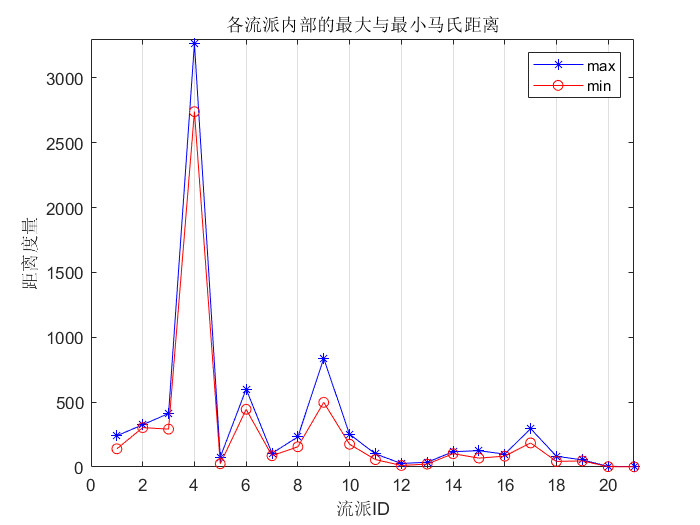

x_arr = 1:1:(c/3);
plot(x_arr,M(1, :),'-*b',x_arr,M(2, :),'-or'); %线性，颜色，标记
axis([0,c/3,0,3300])  %确定x轴与y轴框图大小
legend('max','min');   %右上角标注
xlabel('流派ID')  %x轴坐标描述
ylabel('距离度量') %y轴坐标描述

set(gca,'XGrid','on','YGrid','off')
title('各流派内部的最大与最小马氏距离')

使用重心法算出不同流派之间的马氏距离，保存在G中，然后分别取最小和最大值

G = mandist(x);
G = G(G~=0);
G_max = max(G);
G_min = min(G);
disp(G_min);

    0.3111



disp(G_max)

    5.1057



导入data_by_year，然后与每一流派的平均值做对比，以此来确定流派随时间的变动

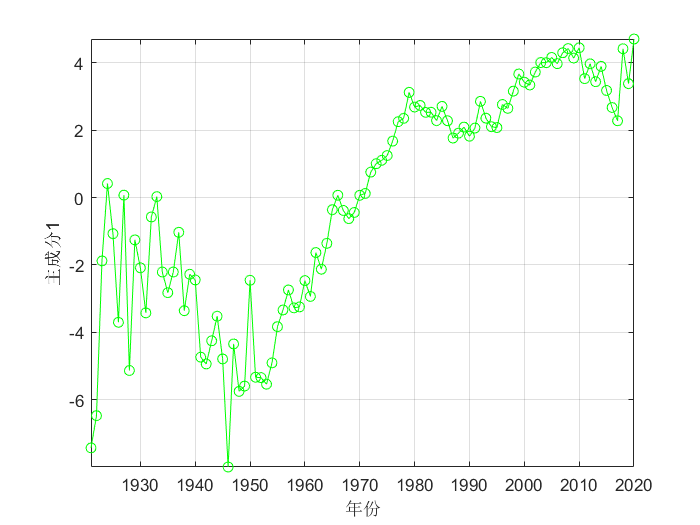

Mat_2 = csvread('./2021_ICM_Problem_D_Data/data_by_year(降维后).csv');
x_arr = Mat_2(:, 1);
y_arr_1 = Mat_2(:, 8);
y_arr_2 = Mat_2(:, 9);
plot(x_arr, y_arr_1, '-og');
xlabel('年份')
ylabel('主成分1')

xlim([1948.6 2020.0])
ylim([-6.04 4.09])
grid on
colorbar

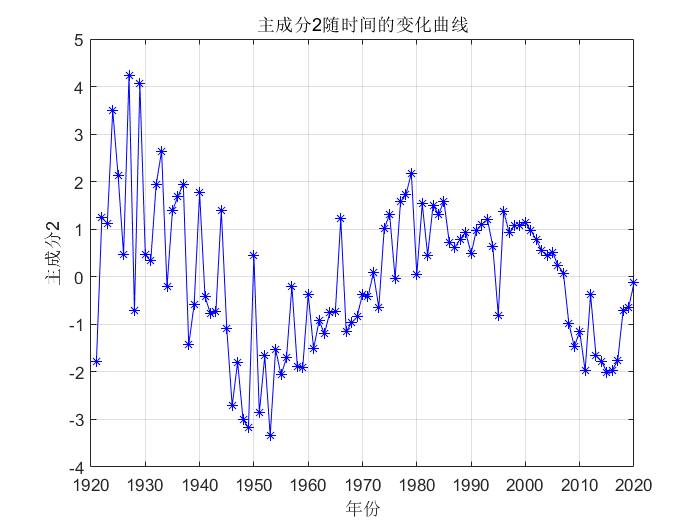


plot(x_arr, y_arr_2, "-*b");
xlabel('年份')
ylabel('主成分2')

grid on
title('主成分2随时间的变化曲线')

下面根据不同年份各流派的音乐家的数量来表示

Mat_3 = csvread("./2021_ICM_Problem_D_Data/year_genres.csv")

Mat_3 =      1     0     0    45    14     2     1     3    11    39     6     3     2     0    17     8     0     3     0     0     0
     2     0     1    81    32     1    17     6    17    41     7     7     8     1    20     1     0     3     0     0     0
   103     0     3   102    60     5   104     4    29    39    22     7     9     1    35    13     0     2     0     2     0
   410     4    36    66    51    13   128     6    41    13    31     3    20     3    15     3     3     9     0     0     0
   419    10    38    45    60     3   109     2    20    14    12     1    17     2     8    11    12    11     1     1     0
   612    37    25    34    42     8    81     2    41     6     7     0    11     0     4     4    11    24     2     0     0
   665    90    25    26    74     9   114     4    54     7     8     1    10     2     2     5     6    26     0     1     0
   480    51    13     7    45     5    80     0    15     3     2     0     4     2     0     5     6 

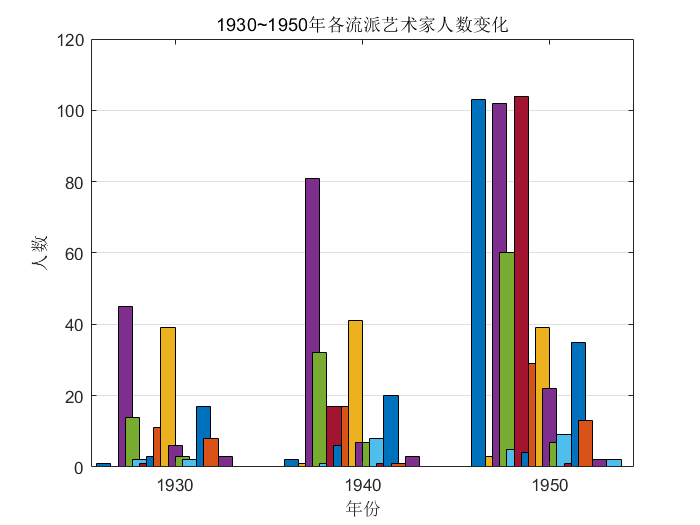

x_arr = 1930:10:1950;
bar(x_arr, Mat_3(1:3,:), 2, "grouped","BarWidth",G_max)

title('1930~1950年各流派艺术家人数变化')
xlabel('年份')
ylabel('人数')

set(gca,'XGrid','off','YGrid','on')

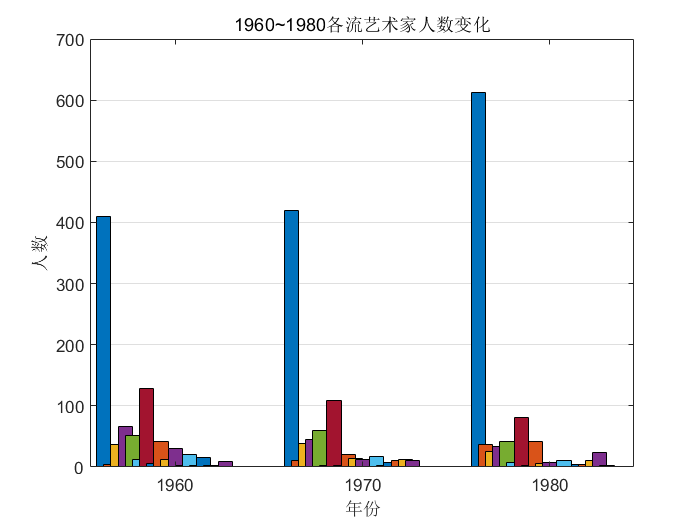

x_arr = 1960:10:1980;
bar(x_arr, Mat_3(4:6,:), 2, "grouped","BarWidth",G_max)

title('1960~1980各流艺术家人数变化')
xlabel('年份')
ylabel('人数')

set(gca,'XGrid','off','YGrid','on')

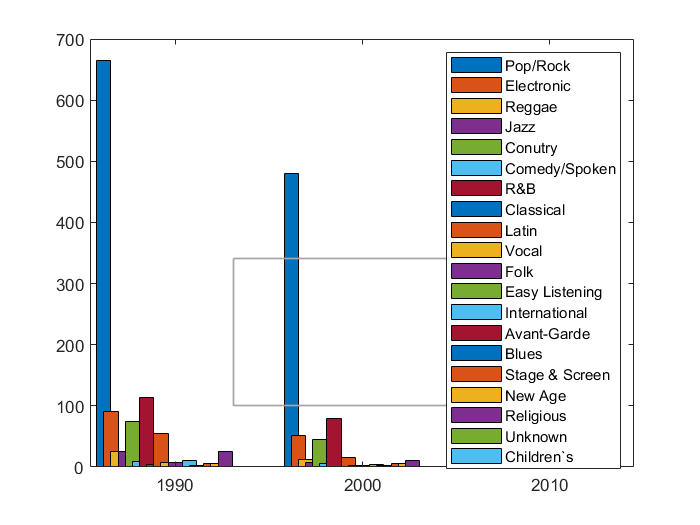

x_arr = 1990:10:2010;
bar(x_arr, Mat_3(7:9,:), 2, "grouped","BarWidth",G_max)
legend('Pop/Rock', 'Electronic', 'Reggae','Jazz','Conutry','Comedy/Spoken','R&B','Classical','Latin','Vocal','Folk','Easy Listening','International','Avant-Garde','Blues','Stage & Screen','New Age','Religious', 'Unknown', 'Children`s')
%xlim([1924.4 2015.6])
ylim([0 700])

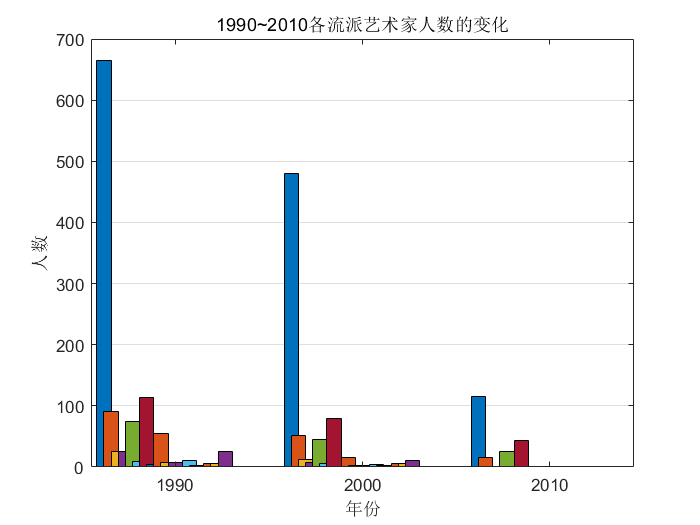


xlim([1985.5 2014.5])
ylim([0 700])
title('1990~2010各流派艺术家人数的变化')
xlabel('年份')
ylabel('人数')
legend('Pop/Rock', 'Electronic', 'Reggae','Jazz','Conutry','Comedy/Spoken','R&B','Classical','Latin','Vocal','Folk','Easy Listening','International','Avant-Garde','Blues','Stage & Screen','New Age','Religious', 'Unknown', 'Children`s')

set(gca,'XGrid','off','YGrid','on')
legend off

对于各流派之间的联系，我们采用聚类分析(x保存了各流派的重心)

x

x =    -1.1971   -0.1937    0.0402    0.2808   -2.5833   -0.9700   -0.4032    0.4670    0.1906    0.2983   -1.9872   -2.0112   -1.1772   -0.2239   -0.9934   -0.2190    0.2966   -2.1707   -0.4466   -0.3126    0.5607
    0.0038    0.1171    0.2890   -0.3823   -0.5577    0.3862    0.4720    1.3296    0.5920    0.6206   -0.7596    0.1011   -0.2419    0.5842    0.2150   -0.3878    0.1181   -0.5286    0.1247    0.9885    0.0146
    0.1019   -0.0139    0.3010    0.0522   -0.0383   -0.1571    0.0346   -0.2063   -0.2009   -0.0166   -0.0812   -0.0228    0.1899    0.1652    0.2343    0.1599   -0.5139   -0.0569    0.0368    0.6183    0.5722


d = pdist(x', 'cityblock');
dc = squareform(d)

dc =          0    1.2326    1.7215    1.9136    2.0878    0.8685    1.3295    3.2982    2.2788    2.2307    1.7365    1.0362    0.3537    1.6169    0.5472    1.4278    2.2239    1.6647    0.9365    2.3856    2.2389
    1.2326         0    0.7206    1.0401    3.0888    1.1885    0.6129    2.0656    1.0462    0.9981    2.7374    1.8424    1.5464    0.6764    1.1458    0.7041    0.9913    2.6656    0.3111    1.6225    1.4431
    1.7215    0.7206         0    1.1605    3.8094    1.5655    0.8928    1.9748    0.9553    0.9072    3.4580    2.5630    1.8593    0.6951    1.1743    1.0770    1.2422    3.3863    0.9153    1.3697    1.0661
    1.9136    1.0401    1.1605         0    3.1300    2.2286    1.5559    2.1567    1.3177    1.0892    2.7786    2.8505    1.7360    1.5841    2.0535    0.6130    1.0824    2.7068    1.2497    2.5303    1.1967
    2.0878    3.0888    3.8094    3.1300         0    2.6760    3.2828    5.1057    4.0862    4.0815    0.8410    1.2464    1.9501    3.7047    2.6351 

z = linkage(d)

z =     2.0000   19.0000    0.3111
    9.0000   10.0000    0.3206
    1.0000   13.0000    0.3537
    7.0000   22.0000    0.3930
   14.0000   25.0000    0.4220
   11.0000   18.0000    0.4388
    5.0000   27.0000    0.4604
   15.0000   24.0000    0.5472
    6.0000   29.0000    0.5860
    4.0000   16.0000    0.6130


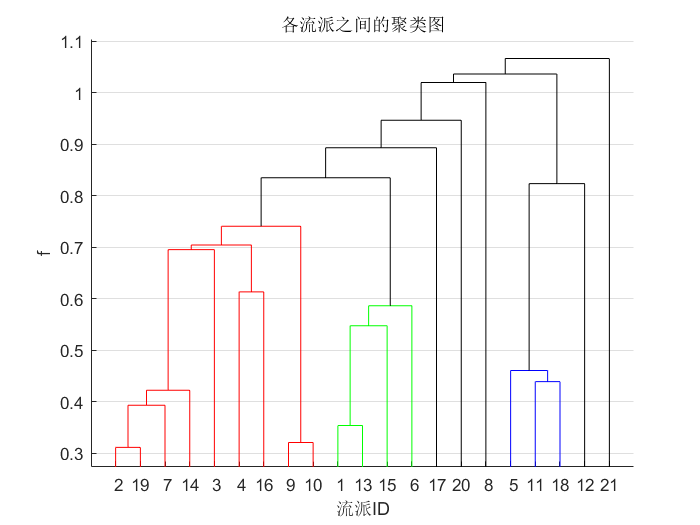

dendrogram(z,'ColorThreshold',"default")

title('各流派之间的聚类图')
xlabel('流派ID')
ylabel('f')

xlim([0.0 22.0])
ylim([0.273 1.104])
set(gca,'XGrid','off','YGrid','on')

T = cluster(z, 'maxclust', 3)

T =      2
     2
     2
     2
     1
     2
     2
     2
     2
     2


for i = 1:3
    tm = find(T == i);
    tm = reshape(tm, 1, length(tm));
    fprintf('第%d类的有%s\n', i, int2str(tm));
end

第1类的有5  11  12  18
第2类的有1   2   3   4   6   7   8   9  10  13  14  15  16  17  19  20
第3类的有21
